## Radiance to Irradiance

The oiCompute() function converts scene radiance into optical image irradiance.  Here are some example values.

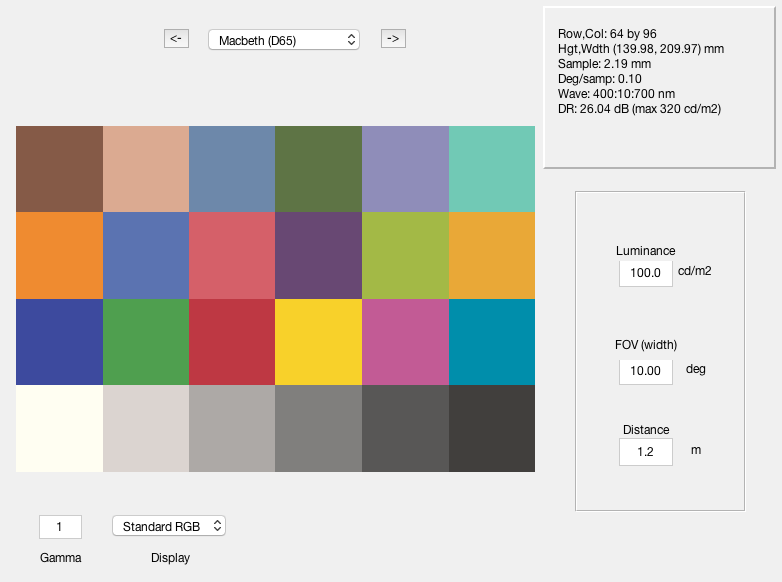

ieInit;
scene = sceneCreate;
ieAddObject(scene); sceneWindow;

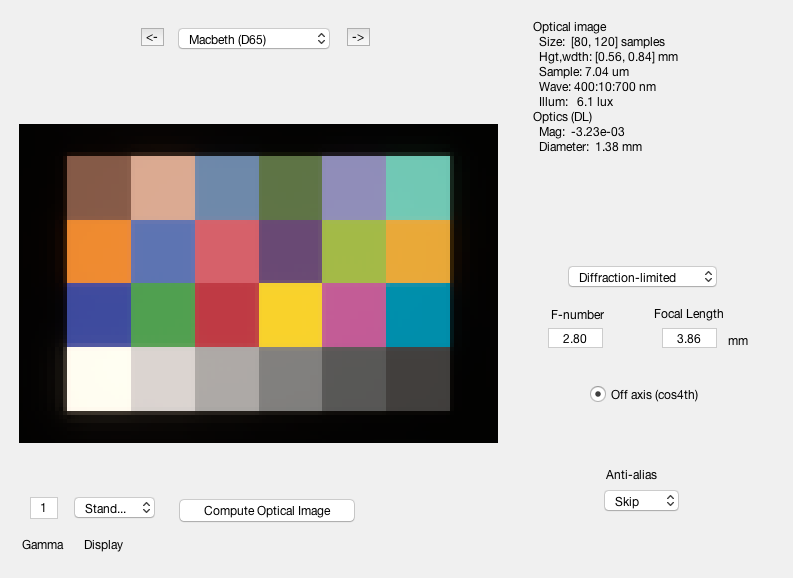


oi = oiCreate;
oi = oiSet(oi,'optics fnumber',2.8);
oi = oiCompute(oi,scene);
ieAddObject(oi); oiWindow;

## Radiance and irradiance plots

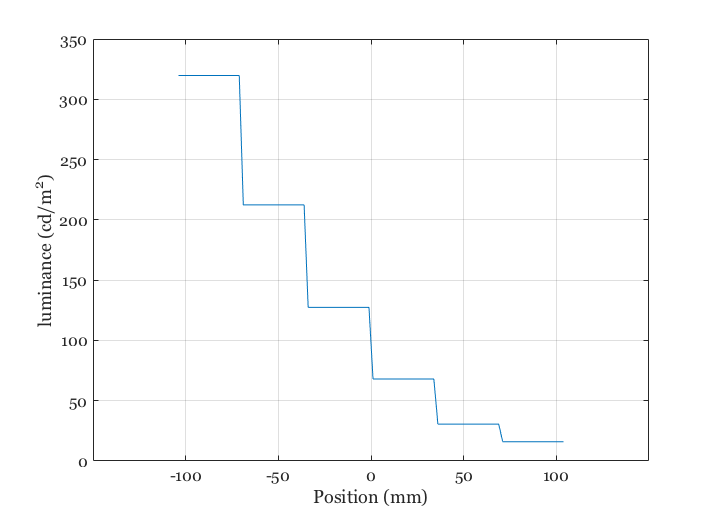

scenePlot(scene,'luminance hline',[1,56]);

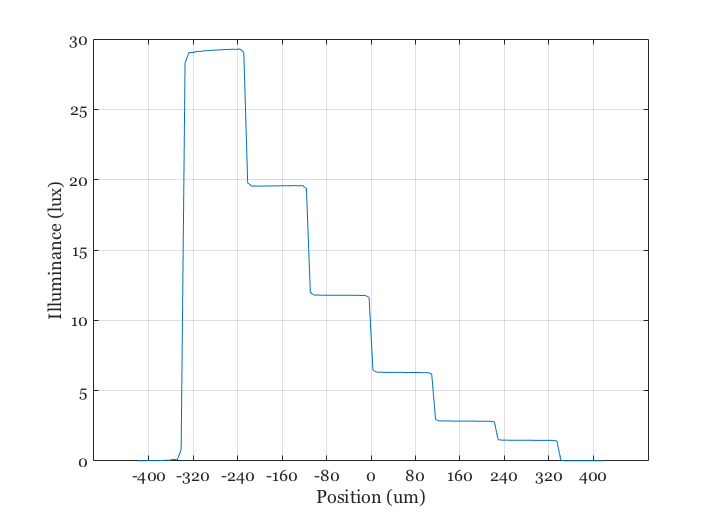


uData = oiPlot(oi,'illuminance hline',[1,72]);

## Change the f/# and re-run

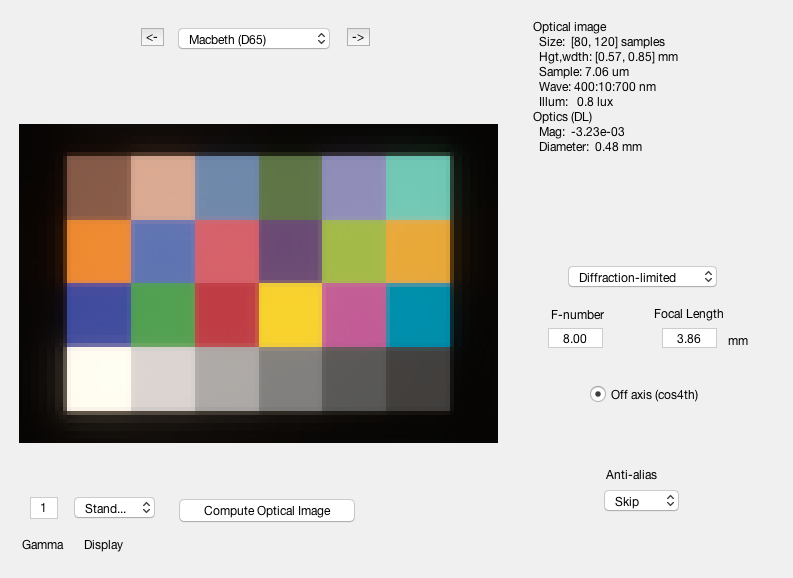

oi = oiSet(oi,'optics fnumber',8);
oi = oiCompute(oi,scene);
ieAddObject(oi); oiWindow;

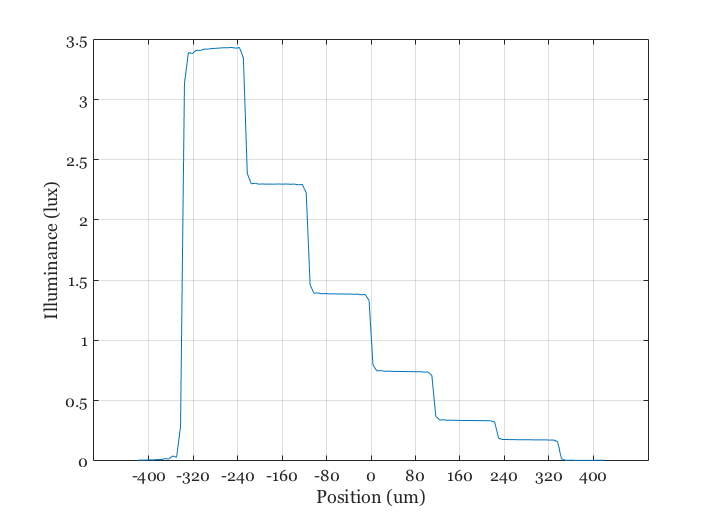

uData2 = oiPlot(oi,'illuminance hline',[1 72]);

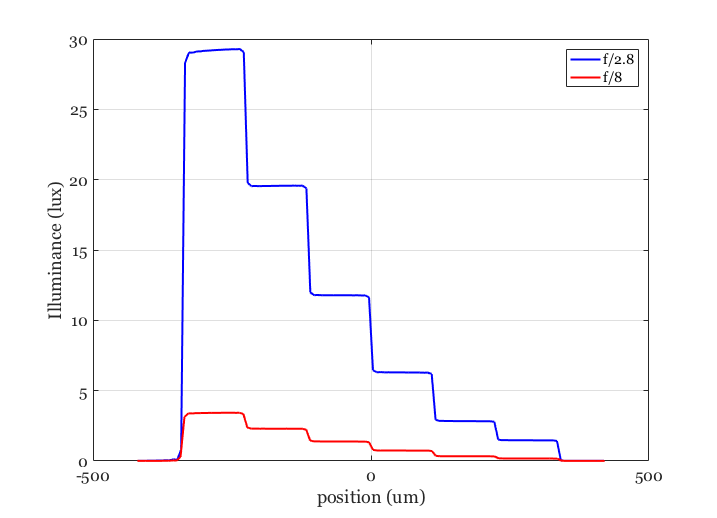


vcNewGraphWin;
p = plot(uData.pos,uData.data,'b',...
    uData2.pos,uData2.data,'r-',...
    'linewidth',2);
legend({'f/2.8','f/8'})
grid on; xlabel('position (um)'); ylabel('Illuminance (lux)')